clear;
M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
C_ = C(2,:)

C_ =      0     0     1     0


D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];

syms t_ch;

Gamma_f = [0, -0.5, 0, 0, 0, 0, 0, 0, 0, 0;
    0.5, 0, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, -1, 0, 0, 0, 0, 0, 0;
    0, 0, 1, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, -1.5, 0, 0, 0, 0;
    0, 0, 0, 0, 1.5, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, -2, 0, 0;
    0, 0, 0, 0, 0, 0, 2, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, -2.5;
    0, 0, 0, 0, 0, 0, 0, 0, 2.5, 0;];

%eGf_t = simplify(expm(Gamma_f*t_ch));

w_0 = [1; 0; 1; 0; 1; 0; 1; 0; 1; 0];
x_0 = [0.01; 0.01; 0.01; 0.01];
%ww = eGf_t*w_0;

Yf = [0, 1, 0.4*sqrt(2), 0.4*sqrt(2), 0.3*sqrt(3), 0.3, -0.2*sqrt(2), 0.2*sqrt(2), 0.1, 0.1*sqrt(3)];
%ff = Y*ww;

eig_G_f = eig(Gamma_f);
I = eye(4);
K = [3064, 4364, -26684, -11174];
%{
for i=1:10
    disp(eig_G_f(i));
    ch_m = [A+B*K-I*eig_G_f(i), B;
        C_, 0]
    ch_r = rank(ch_m);
    disp(ch_r);
end
%}



cvx_begin sdp
variable Pf(4, 10)
variable Kf(1, 10)

Pf*Gamma_f-(A+B*K)*Pf-D*Yf == B*Kf;
C_*Pf == 0;

cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Kf

Kf = 1.0e+03 *

   -0.7361   -1.0567   -0.3674    0.0490   -0.1453    0.0861   -0.0272   -0.0768   -0.0319    0.0036


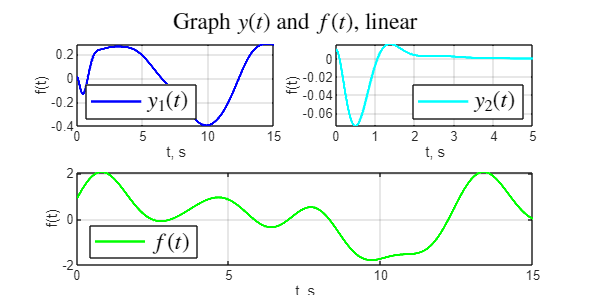



%========Моделирование линейной ========
%{
open_system('task_5_f_lin');
set_param('task_5_f_lin/f_', 'VariableName', 'f_')
set_param('task_5_f_lin/y', 'VariableName', 'y')
out = sim('task_5_f_lin');

figure('Position', [100 100 800 400])

subplot(2,2,1);
plot(out.y.Time, out.y.Data(1,:),'b-', 'LineWidth',1.5);

legend('$y_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southwest')
ylabel('f(t)')
xlabel('t, s')
grid()


subplot(2,2,2);
plot(out.y.Time, out.y.Data(2,:),'c-', 'LineWidth',1.5);
legend('$y_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlim([0 5])
xlabel('t, s')
grid()

subplot(2,2,[3 4]);
plot(out.y.Time,out.f_.Data,'g-', 'LineWidth',1.5);
legend('$f(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southwest')
ylabel('f(t)')
xlabel('t, s')
grid()


sgtitle('Graph $y(t)$ and $f(t)$, linear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\5_f_lin.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

%}
